In this problem you will use H∞ and H2 synthesis techniques to design a roll angle hold

control system for a fixed wing UAS with actuator dynamics. The roll dynamics are given by

### A)

% x_dot = Ax + Bu
% X = [P; phi, del_a] (roll rate, roll, aileron deflection)
% u = voltage
tau = 0.1;
Lp = -1;
Lda = 30;

A = 0.0005;		   % low value for good tacking
M = 10;			   % higher value for good disturbance rejection
omega_b = 1.8 / 3; % 1.8 / rise time = omega

s = tf('s');
W1 = ((s / M) + omega_b) / (s + (omega_b * A));
W2 = 100 * (s + 0.1) / (s + 100);

A = [Lp 0 Lda;
	1 0 0;
	0 0 -1/tau];

B = [0; 0; 1/tau];

C = [0 1 0];

D = 0;

### B)

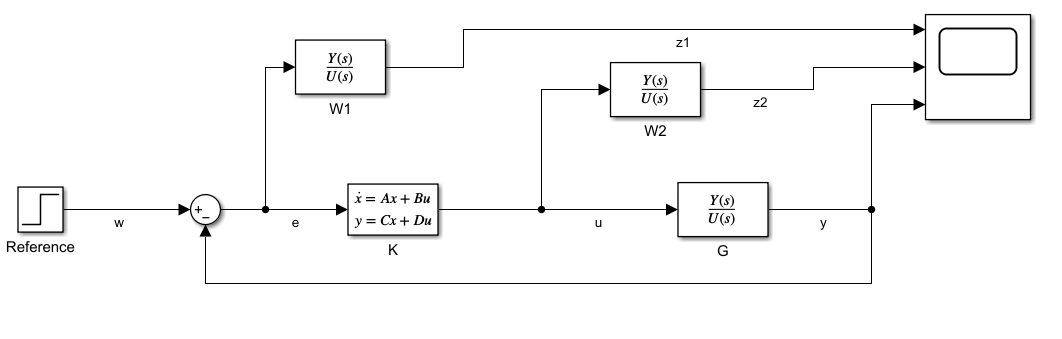

### C)

G = ss(A, B, C, D);

systemnames = 'G W1 W2';
inputvar = '[w; u]';
outputvar = '[ W1; W2; w - G]';
input_to_G = '[u]';
input_to_W1 = '[w-G]';
input_to_W2 = '[u]';
sysoutname = 'P';
sysic;
P = minreal(ss(P))

P =
 
  A = 
            x1       x2       x3       x4       x5
   x1       -1        0       30        0        0
   x2        1        0        0        0        0
   x3        0        0      -10        0        0
   x4        0       -1        0  -0.0003        0
   x5        0        0        0        0     -100
 
  B = 
         w    u
   x1    0    0
   x2    0    0
   x3    0   10
   x4    1    0
   x5    0  128
 
  C = 
               x1      x2      x3      x4      x5
   [+W1]        0    -0.1       0     0.6       0
   [+W2]        0       0       0       0  -78.05
   [+w-G]       0      -1       0       0       0
 
  D = 
             w    u
   [+W1]   0.1    0
   [+W2]     0  100
   [+w-G]    1    0
 
Continuous-time state-space model.




hinfnorm(W1)

ans = 2000

### D)

n_meas = 1;
n_ctrl = 1;
[K,CL,GAM,info] = hinfsyn(P, n_meas, n_ctrl, 'method', 'ric', 'Tolgam', 1e-3, 'Display', 'on');


  Test bounds:  0.2385 <=  gamma  <=  0.8309

    gamma        X>=0        Y>=0       rho(XY)<1    p/f
  4.452e-01    -2.5e+00 #  -6.6e-20     3.371e-16     f
  6.082e-01     1.9e-07     0.0e+00     3.296e-06     p
  5.204e-01    -1.5e+01 #  -3.6e-16     1.306e-16     f
  5.626e-01     1.9e-07     1.1e-19     1.430e-05     p
  5.411e-01    -6.3e+01 #  -1.5e-18     2.041e-16     f
  5.517e-01     2.0e-07     2.5e-22     6.023e-05     p
  5.464e-01    -2.4e+02 #   6.5e-20     2.008e-16     f
  5.490e-01     2.0e-07     2.0e-22     2.806e-04     p
  5.477e-01    -7.8e+02 #  -1.9e-18     1.984e-16     f
  5.484e-01     2.0e-07     6.4e-20     3.104e-03     p
  5.480e-01    -1.8e+03 #   6.4e-20     1.996e-16     f
  Limiting gains...
  5.486e-01     2.0e-07     0.0e+00     7.331e-04     p
  5.486e-01     2.0e-07     0.0e+00     7.347e-04     p

  Best performance (actual): 0.5486


So = minreal(inv(eye(1) + (G * K)));

4 states removed.


To = minreal(G * K / (eye(1) + (G * K)));

11 states removed.



[K2,CL2,GAM2,info2] = h2syn(P, n_meas, n_ctrl);

So2 = minreal(inv(eye(1) + (G * K2)));

2 states removed.


To2 = minreal(G * K2 / (eye(1) + (G * K2)));

9 states removed.


### E)

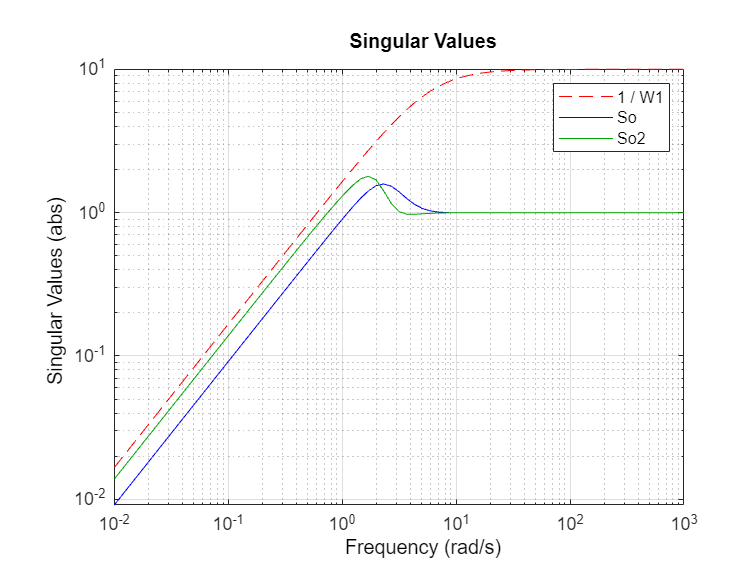

figure
sigma(inv(W1), 'r--', So, 'b', So2, 'g', {10^-2, 10^3});
legend('1 / W1', 'So', 'So2')

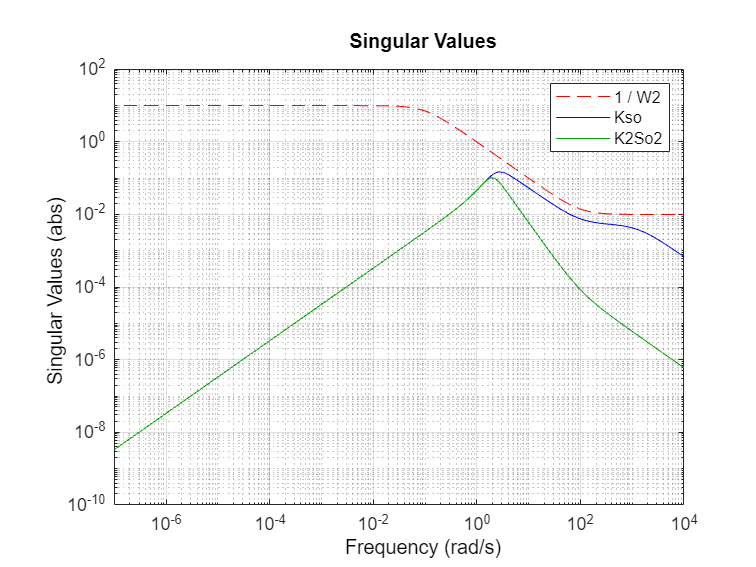


figure
sigma(inv(W2), 'r--', K*So, 'b', K2*So2, 'g');
legend('1 / W2', 'Kso', 'K2So2')

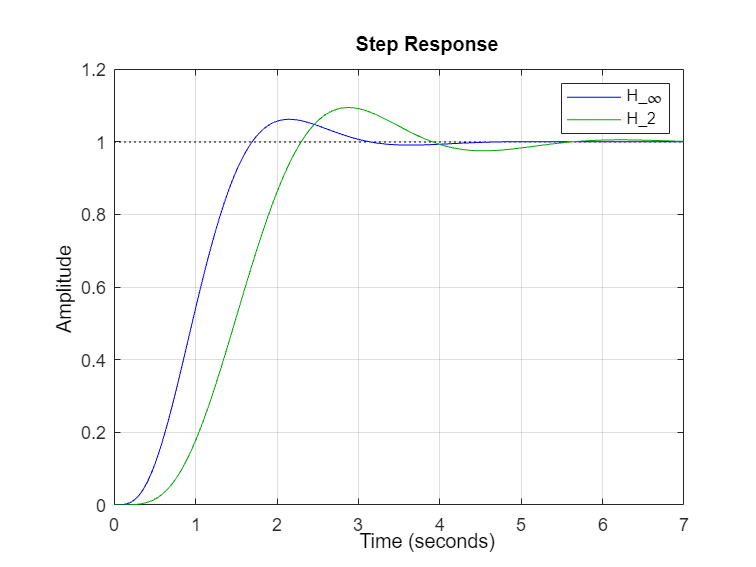


figure
grid on
step(To, 'b', To2, 'g')
legend('H_{\infty}', 'H_2')

### F)

The H2 controller can't easily be tuned to meet requirements. This is due to the lack of a direct relationship between the requirements and the solver. We can see that the H2 controller does meet the specifications so no further tuning is needed.